# Examen Enero 2017

## Introducción

La empresa Dolby nos ha contratado para realizar una implementación particular de su sistema de sonido Dolby Atmos para el ámbito doméstico. Nuestro cometido es el de realizar toda la programación del sistema de sonido envolvente, dejando de lado el algoritmo de descompresión del stream de audio.

El requerimiento principal de la implementación es que debe representar la escena sonora mediante objetos móviles, calculando durante la reproducción el sonido que debe emitir cada altavoz según la posición de la fuente. Además, por requerimientos de hardware se debe procesar el sonido en bloques de 10ms (aprox.) de duración, con longitud potencia de dos y sin empleo de solapamiento. El instante de comienzo de cada bloque será el momento en que se actualizarán todos los parámetros de la escena.

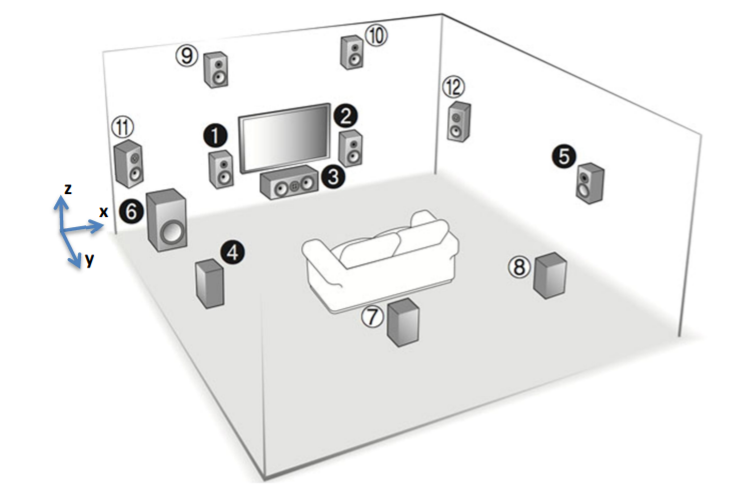

#### Problema 1. Preparación Inicial

Como punto de partida se nos han enviado un archivo en el cual se incluyen dos matrices: altavoces y fuentes. La matriz ‘altavoces’ de dimensiones (12x3), contiene las posiciones de los altavoces. Cada fila representa un altavoz y cada columna la coordenada x, y, z. Por otro lado, la matriz ‘fuente’, de dimensiones (2x3), contiene en su primera fila la posición inicial de la fuente y en la segunda la posición final.

En ambos casos, las posiciones están expresadas en metros y el origen de coordenadas se encuentra situado en la esquina inferior izquierda de la sala (junto al altavoz 6). 

Carga el fichero de datos proporcionado (datos.mat) en memoria emplea para ello la función load, y comprueba por pantalla el contenido de cada matriz. 

Carga además el fichero de sonido ‘prueba.wav’. Determina el número de muestras que contiene (L), y el número de bloques de sonido (N) necesarios para procesar en su totalidad el fichero de audio cargado. Téngase en cuenta que si al final del fichero queda un bloque de datos incompleto, éste deberá ser desechado. 

Por último, deberemos reservar memoria para la matriz ‘salida’ la cual llenaremos de ceros. Esta matriz será la salida final del algoritmo, sus dimensiones serán (12xL) y contendrá una pista de sonido para cada uno de los altavoces (12 altavoces x L muestras por altavoz)

Cargamos el archivo datos.mat, dónde:

Altavoces (12x3) -> Posiciones de los altavoces

Fuente (2x3) -> Posición inicial y final de la fuente

load('datos.mat');

Empezamos cargando el audio y transponiendolo

[x, fs] = audioread('prueba.wav');
x = x(:)';

Número de altavoces que tenemos

NumAlt = size(altavoces, 1);

Obtenemos la longitud del audio

Long_Audio = length(x);

En el enunciado nos proporcionan el tiempo para cada bloque

Tiempo_Bloque = 0.1;

Obtenemos el tamaño que tendrá cada bloque

TamB = fix(fs*Tiempo_Bloque);

Obtenemos el total de bloques que utilizaremos

Bloque_Total = fix(L/TamB);

Inicializamos la variable de salida

salida = zeros(NumAlt, Long_Audio);

#### Problema 2. Cálculo de la trayectoria

Antes de comenzar a recrear la escena es necesario conocer en detalle las trayectorias de todas las fuentes. Por simplicidad el escenario solamente contiene una fuente que se mueve en una trayectoria rectilínea a velocidad constante.  

Las posiciones inicial y final ya las hemos cargado en el ejercicio previo, ahora debemos determinar las coordenadas (x,y,z) de todas las posiciones intermedias por donde pasará la fuente, debiendo obtener una posición para cada bloque de datos (N). Téngase en cuenta que la fuente llegará a la posición final al finalizar el fichero de audio (último bloque). 

La trayectoria interpolada deberá almacenarse en una matriz denominada ‘trayectoria’, cuyas dimensiones deberán ser (Nx3).  

Crearemos la variable que vamos a utilizar, en cada eje tendremos una trayectoria de una trayectoria de un punto por cada bloque, si tenemos 150 bloques, tendremos 150 puntos de la trayectoria

Al tener 3 dimensiones, la variable será:

trayectoria = zeros(Bloque_Total, 3);

Trayectoria Eje X

trayectoria(:,1) = linspace(fuente(1,1), fuente(2,1), Bloque_Total);

Trayectoria Eje Y

trayectoria(:,2) = linspace(fuente(1,2), fuente(2,2), Bloque_Total);

Trayectoria Eje Z

trayectoria(:,3) = linspace(fuente(1,3), fuente(2,3), Bloque_Total);

#### Problema 3. Procesador por bloques

Implementa el esquema de procesado por bloques sin solapamiento requerido para poder recorrer en su totalidad el fichero de sonido de la fuente (bucle principal).

Utilizaremos una ventana hanning

V = hanning(N_Bloque);

Invertimos el vector de la ventana para dejarlo en horizontal como a x

V = V(:)';

Creamos el bucle que nos servirá para calcular el eventanado de los bloques

for i=1:TotalBloques

Marcamos el inicio y find e cada bloque

    Inicio = 1+N_Bloque*(i-1);
    Fin = (N_Bloque) + (N_Bloque*(i-1));

Obtenemos el eventanado de los bloques

    Envent = X(Inicio:Fin);
    XX = Envent.*V;

    Bloques(Inicio:Fin) = X(Inicio:Fin) +XX;
end

#### Ejercicio 4 Calculo de la imagen Phantom

El algoritmo que emplearemos para localizar espacialmente las fuentes sonoras emplea la siguiente lógica:

- Únicamente emitirán sonido los dos altavoces más cercanos a la posición actual de la fuente. Las distancias de estos dos altavoces a la fuente serán (d1 y d2)

 - La ley panning que debe aplicarse a estos dos altavoces se calculará mediante la ley Seno/Coseno sobre las proporciones de las distancias (ver imagen)

 - Recuerda que el altavoz 6 es el subwoofer por lo que no debe ser tenido en cuenta.  

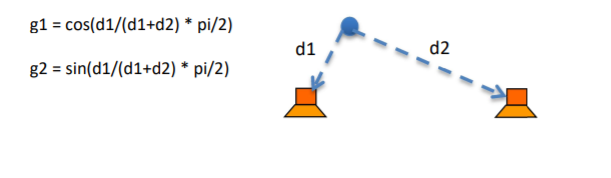

Introduce en el interior del esquema de procesado por bloques del ejercicio anterior:

- El código necesario para calcular las distancias desde la posición de la fuente para el bloque actual.

- El cálculo de las ganancias a aplicar a cada altavoz para el bloque actual.

- Copia el bloque de sonido resultante a los canales correspondientes de la matriz ‘salida’, aplicando las ganancias calculadas. 

Recuerda que estos cálculos deberán realizarse para cada bloque. 

Generamos el bucle con el cual calcularemos el procesado espacial

for i=1:Bloque_Total

Inicializamos el inicio y final del procesado

    Inicio = 1+TamB*(i-1);
    Fin = (TamB) + (TamB*(i-1));

Cortamos el bloque que vamos a procesar

    Bloque = x(Inicio:Fin);

Calcula la distancia y el indice de altavoz que más se activa

    DifTrayec = zeros(NumAlt, 3);
    DistAlt = zeros(1, NumAlt);

Calculo de las distancias para 1 muestra, para todos los altavoces

    for n=1:NumAlt
        if i==6

Este sería el subwoofer, dónde no aplicamos nada

        else

Aquí calcularemos la difracción y la distancia

            DifTrayec(n,:) = trayectoria(i,:) - altavoces(n,:);
            DistAlt (1,n) = sqrt((DifTrayec(n,1)^2) + (DifTrayec(n,2)^2) + (DiftTrayec(n,3)^2));

        end
    end

Obtenemos las distancias ordenadas de menor a mayor y la posición en el vector original, así podemos saber de que altavoz se trata

    [Distancias_Ordenadas, posicion] = sort(DistAlt);


Nos guardaremos las dos distancias más pequeñas puesto que serán los dos altavoces más cercanos a la posición actual de la fuente

    d1 = Distancias_Ordenadas(1);
    d2 = Distancias_Ordenadas(2);


Obtenemos la ganancia para cada altavoz

    g1 = cos((d1/(d1+d2))*(pi/2));
    g2 = sin((d1/(d1+d2))*(pi/2));


Multiplicamos cada gananica por el bloque en el que estamos

    g1_Alt1 = Bloque*g1;
    g2_Alt2 = Bloque*g2;


Guardamos lo obtenido previamente en el vector de salida. Utilizamos la posición para saber de que altavoz se trata

    salida(posicion(1), Inicio:Fin) = g1_Alt1;
    salida(posicion(2), Inicio:Fin) = g2_Alt2;
end

#### Problema 5. Efectos en baja frecuencia

El subwoofer de un sistema de sonido se emplea como un canal especial, el cual no entra dentro del algoritmo de posicionamiento de las fuentes sonoras. En su lugar este altavoz emite el sonido combinado de baja frecuencia del resto de canales. 

Implementa el procesado del subwoofer, el cual consiste en la suma simultanea de las señales de todos los canales, y un posterior filtrado paso bajo a 60 Hz. 

Deberá diseñarse previamente un filtro butterworth de 2º orden con frecuencia de corte 60Hz. El sonido resultante deberá introducirse en el canal 6 que corresponde al subwoofer. 

Sumar todas las señales en cada muestra

Suma_Canales = sum(salida,1);

Tenemos una frecuencia de corte del fitro

Fc = 60;
w = (pi*fc*2)/fs;

Orden del filtro

Orden = 2;

Obtenemos los coeficientes para el filtro butter de orden 2

[B,A] = butter(Orden, w);

FIltramos con la función filter, con los coeficientes obtenidos del filtro butter y la señal a filtrar

Bass = filter(B,A, SUma_Canales);

Copiamos la señal obtenida en su posición de la amtriz salida

salida(6,:) = Bass

Normalizamos todas las señales para cada altavoz

for i=1:NumAlt
    salida(i,:) = salida(i,:)/(abs(max(salida(i,:)))+eps);
end

#### Problema 6 Reducción de la distorsión por ganancia

Al realizar el procesado por bloques obtenemos un valor de ganancia diferente en cada bloque lo cual, en determinadas situaciones, introduce cierta distorsión si el valor anterior y el actual son sensiblemente diferentes. ¿Se te ocurre alguna forma de minimizar esta distorsión? 

Describe que algoritmo implementarías para minimizar esta distorsión.  

Respuesta:

Cuando intentamos aumentar el volumen, lo que hacemos es multiplicar la señal por una Ganancia. Al ser procesado por bloques, la Ganancia se aplica al bloque completo. La Ganancia puede variar una vez por bloque. Distorsión: Un simple cambio en la Ganancia produce una gran distorsión. Para minimizar la distorsión hay dos posibilidades:

-> Aplicar más de una Ganancia por bloque .> Mejor cantidad: Una por muestra (ganancias de interpolación).

-> Actualizar los parámetros en el momento adecuado 

-> Cruces por cero.

 Ganancia = Ganancia / max( abs( Ganancia ) );